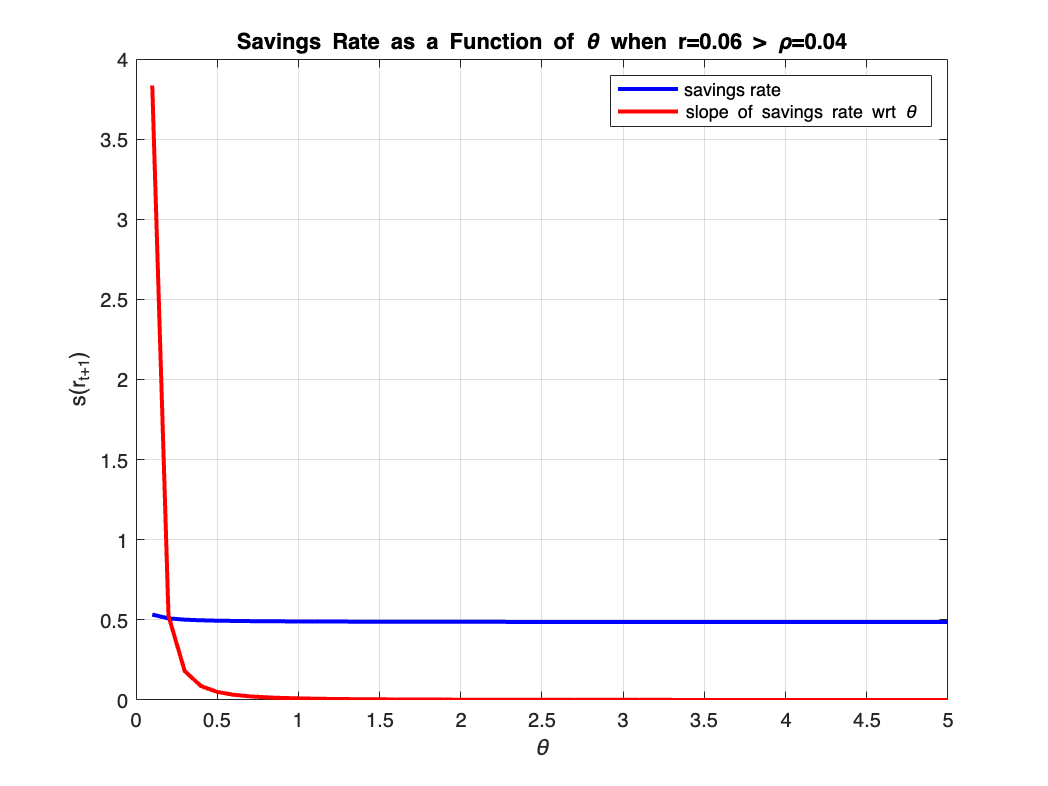

% Plot savings rate over range of thetas from OLG model
clear;
theta = 0.1:0.1:5; % Range of theta
rt1 = 0.06; % Interest rate
rho = 0.04; % Discount rate

s = ((1+rt1).^((1-theta)./theta)) ./ ((1+rho).^(1./theta) + (1+rt1).^((1-theta)./theta));
dS_dTheta = (-s ./ theta.^2) .* ((1+rho).^(-1./theta) .* log(1+rho) - (1+rt1).^((1-theta)./theta) .* log(1+rt1));

figure;
plot(theta, s, 'b', 'LineWidth', 2);
hold on
plot(theta, dS_dTheta, 'r', 'LineWidth', 2);
xlabel('\theta');
ylabel('s(r_{t+1})');
title('Savings Rate as a Function of \theta when r=0.06 > \rho=0.04');
legend('savings rate','slope of savings rate wrt \theta');
grid on;

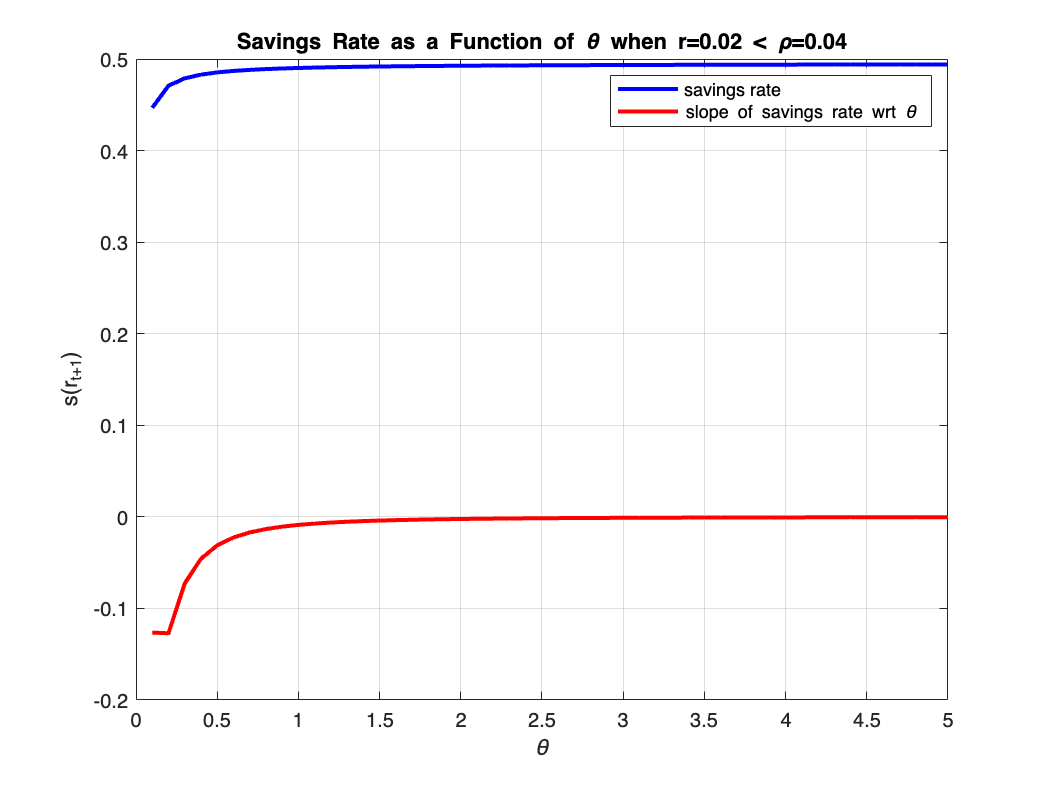

% Plot savings rate over range of thetas from OLG model
clear;
theta = 0.1:0.1:5; % Range of theta
rt1 = 0.02; % Interest rate
rho = 0.04; % Discount rate

s = ((1+rt1).^((1-theta)./theta)) ./ ((1+rho).^(1./theta) + (1+rt1).^((1-theta)./theta));
dS_dTheta = (-s ./ theta.^2) .* ((1+rho).^(-1./theta) .* log(1+rho) - (1+rt1).^((1-theta)./theta) .* log(1+rt1));

figure;
plot(theta, s, 'b', 'LineWidth', 2);
hold on
plot(theta, dS_dTheta, 'r', 'LineWidth', 2);
xlabel('\theta');
ylabel('s(r_{t+1})');
title('Savings Rate as a Function of \theta when r=0.02 < \rho=0.04');
legend('savings rate','slope of savings rate wrt \theta');
grid on;
hold off

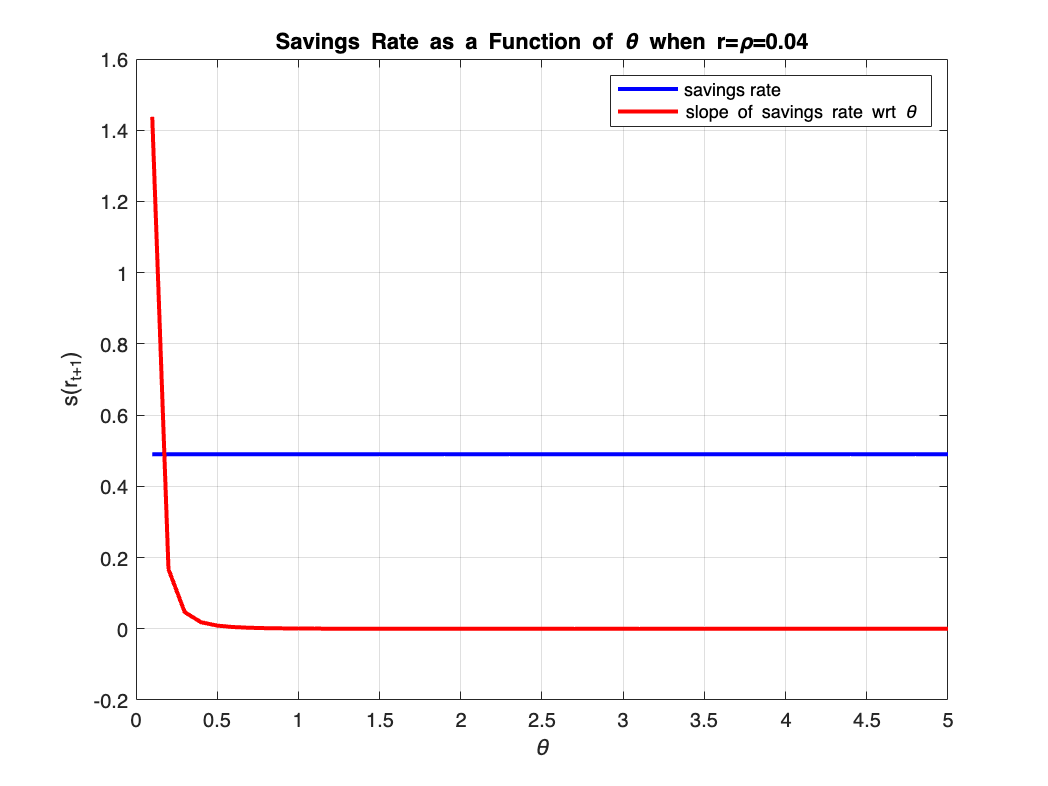

% Plot savings rate over range of thetas from OLG model
clear;
theta = 0.1:0.1:5; % Range of theta
rt1 = 0.04; % Interest rate
rho = 0.04; % Discount rate

s = ((1+rt1).^((1-theta)./theta)) ./ ((1+rho).^(1./theta) + (1+rt1).^((1-theta)./theta));
dS_dTheta = (-s ./ theta.^2) .* ((1+rho).^(-1./theta) .* log(1+rho) - (1+rt1).^((1-theta)./theta) .* log(1+rt1));

figure;
plot(theta, s, 'b', 'LineWidth', 2);
hold on
plot(theta, dS_dTheta, 'r', 'LineWidth', 2);
xlabel('\theta');
ylabel('s(r_{t+1})');
title('Savings Rate as a Function of \theta when r=\rho=0.04');
legend('savings rate','slope of savings rate wrt \theta');
grid on;
hold off

## Surface plot

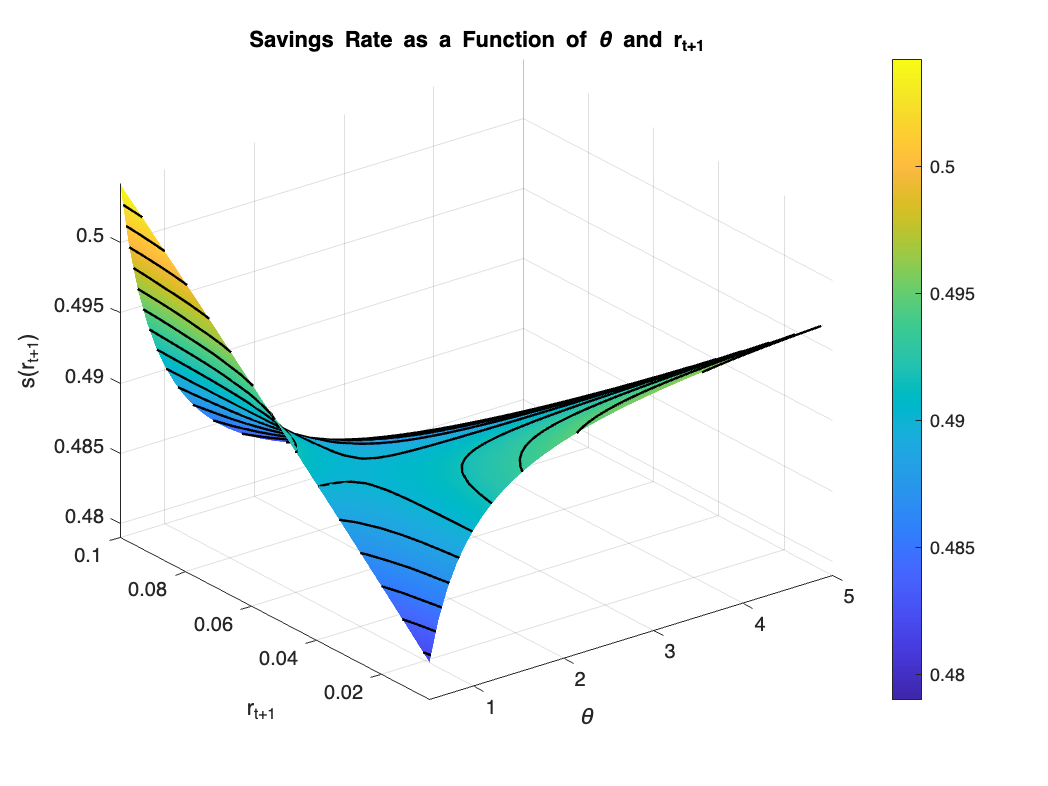

clear;
theta = 0.5:0.1:5;  % Range of theta
rt1 = 0.005:0.005:0.1; % Interest rate range
rho = 0.04; % Discount rate

% Create meshgrid to ensure element-wise computation
[Theta, Rt] = meshgrid(theta, rt1);

% Compute savings rate
S = ((1+Rt).^((1-Theta)./Theta)) ./ ((1+rho).^(1./Theta) + (1+Rt).^((1-Theta)./Theta));

% Create surface plot
figure;
surf(Theta, Rt, S);
hold on;
%surf(Theta, Rt, S, 'EdgeColor', 'none'); % Surface plot with smooth shading
contour3(Theta, Rt, S, 15, 'k', 'LineWidth', 1.2); % Add contour lines in 3D
xlabel('\theta');
ylabel('r_{t+1}');
zlabel('s(r_{t+1})');
title('Savings Rate as a Function of \theta and r_{t+1}');
colorbar;
grid on;
shading interp; % Smooth shading
hold off;

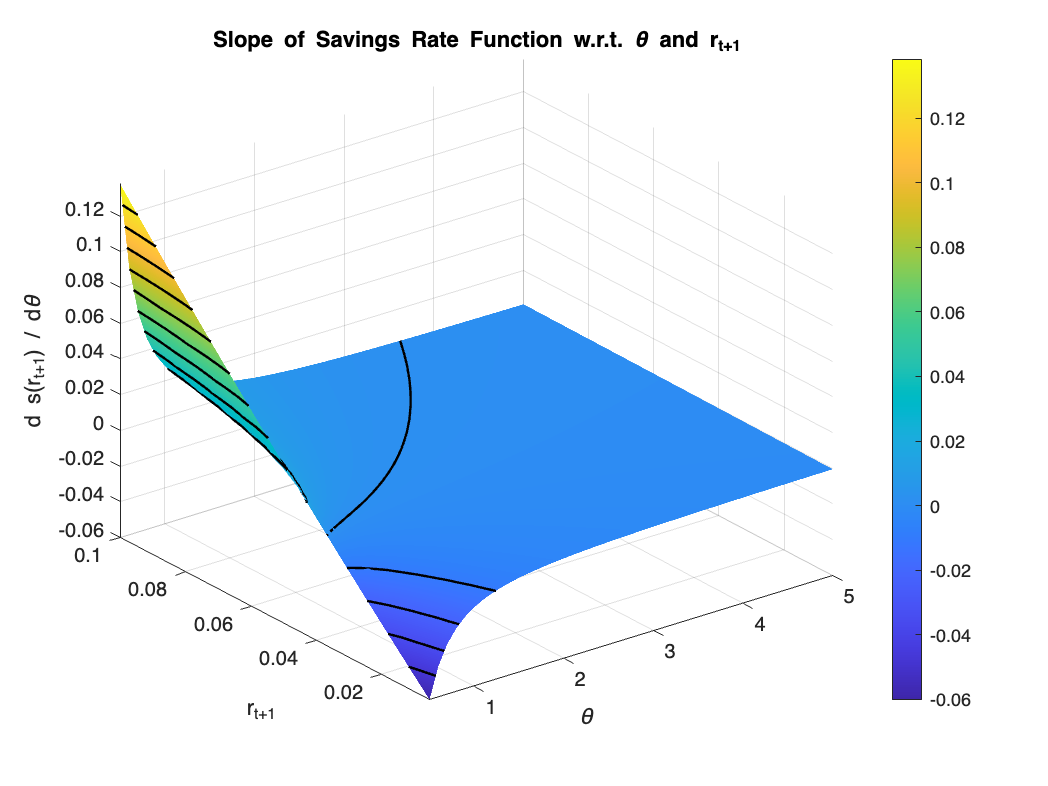

clear;
theta = 0.5:0.1:5;  % Range of theta
rt1 = 0.005:0.005:0.1; % Interest rate range
rho = 0.04; % Discount rate

% Create meshgrid for correct element-wise calculations
[Theta, Rt] = meshgrid(theta, rt1);

% Compute savings rate function
S = ((1+Rt).^((1-Theta)./Theta)) ./ ((1+rho).^(1./Theta) + (1+Rt).^((1-Theta)./Theta));

% Compute slope of savings function w.r.t. theta
dS_dTheta = (-S ./ Theta.^2) .* ((1+rho).^(-1./Theta) .* log(1+rho) - (1+Rt).^((1-Theta)./Theta) .* log(1+Rt));

% Create 3D surface plot for the slope
figure;
surf(Theta, Rt, dS_dTheta, 'EdgeColor', 'none'); % Smooth surface plot
hold on
contour3(Theta, Rt, dS_dTheta, 15, 'k', 'LineWidth', 1.2); % Add contour lines

xlabel('\theta');
ylabel('r_{t+1}');
zlabel('d s(r_{t+1}) / d\theta');
title('Slope of Savings Rate Function w.r.t. \theta and r_{t+1}');
colorbar;
grid on;
shading interp; % Smooth shading for better visualization
hold off

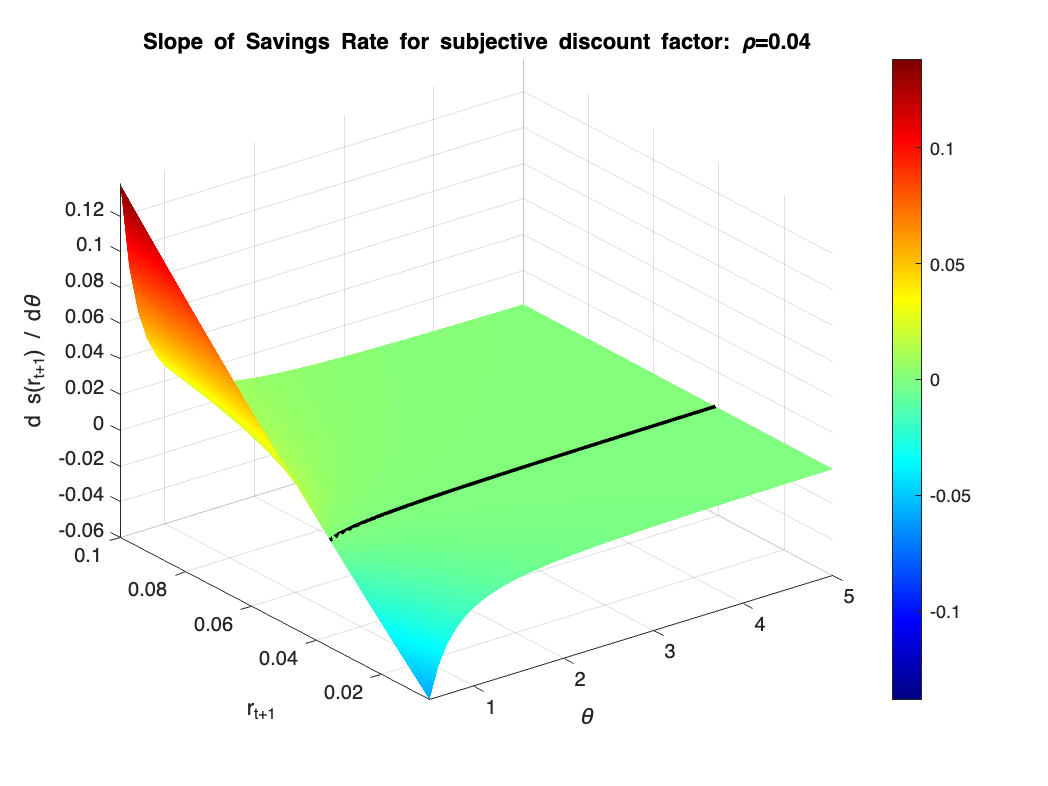

clear;
theta = 0.5:0.1:5;  % Range of theta
rt1 = 0.005:0.005:0.1; % Interest rate range
rho = 0.04; % Discount rate

% Create meshgrid for correct element-wise calculations
[Theta, Rt] = meshgrid(theta, rt1);

% Compute savings rate function
S = ((1+Rt).^((1-Theta)./Theta)) ./ ((1+rho).^(1./Theta) + (1+Rt).^((1-Theta)./Theta));

% Compute slope of savings function w.r.t. theta
dS_dTheta = (-S ./ Theta.^2) .* ((1+rho).^(-1./Theta) .* log(1+rho) - (1+Rt).^((1-Theta)./Theta) .* log(1+Rt));

%% **Plot Slope of Savings Rate (dS/dTheta) and Highlight Negative Regions**
figure;
surf(Theta, Rt, dS_dTheta, 'EdgeColor', 'none'); % Smooth surface plot
hold on;
contour3(Theta, Rt, dS_dTheta, [0 0], 'k', 'LineWidth', 2); % Bold zero-contour line

% Color Mapping: Set negative values to blue, positive to red
colormap(jet); % Blue to Red color gradient
clim([-max(abs(dS_dTheta(:))), max(abs(dS_dTheta(:)))]) % Normalize colormap around zero
colorbar;
xlabel('\theta');
ylabel('r_{t+1}');
zlabel('d s(r_{t+1}) / d\theta');
title('Slope of Savings Rate for subjective discount factor: \rho=0.04');
grid on;
shading interp;
hold off;

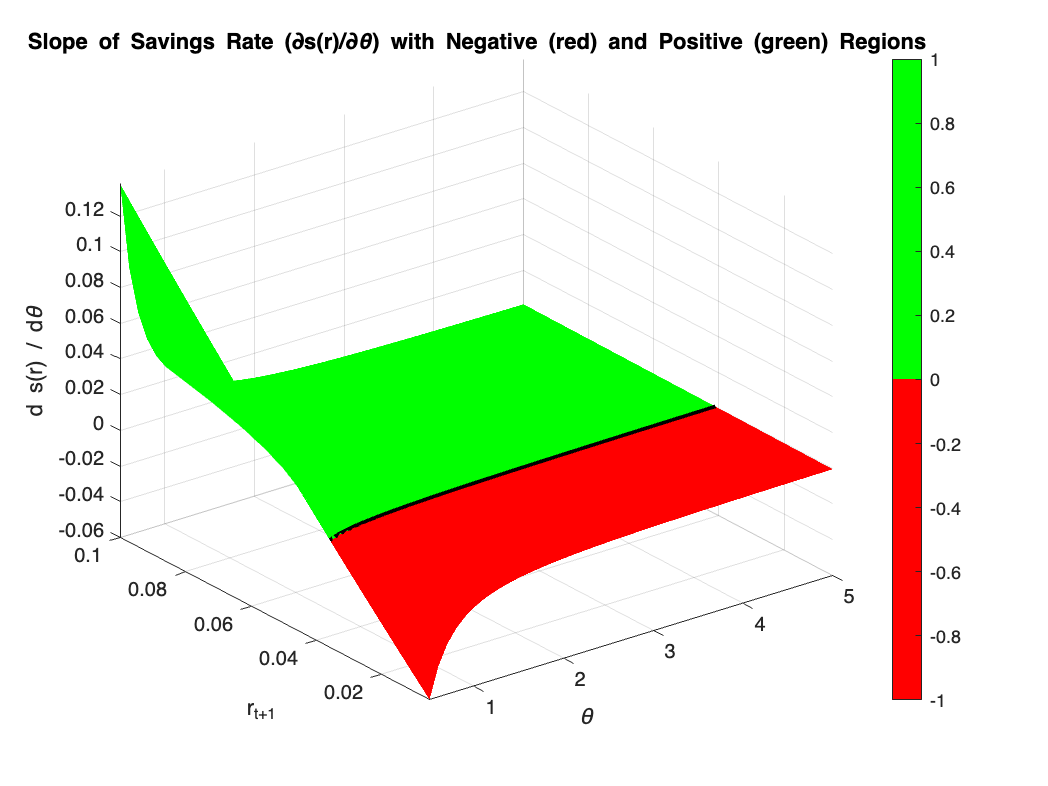

clear;
theta = 0.5:0.1:5;  % Range of theta
rt1 = 0.005:0.005:0.1; % Interest rate range
rho = 0.04; % Discount rate

% Create meshgrid for correct element-wise calculations
[Theta, Rt] = meshgrid(theta, rt1);

% Compute savings rate function
S = ((1+Rt).^((1-Theta)./Theta)) ./ ((1+rho).^(1./Theta) + (1+Rt).^((1-Theta)./Theta));

% Compute slope of savings function w.r.t. theta
dS_dTheta = (-S ./ Theta.^2) .* ((1+rho).^(-1./Theta) .* log(1+rho) - (1+Rt).^((1-Theta)./Theta) .* log(1+Rt));

% Create 3D surface plot for the slope with two-color split
figure;
surf(Theta, Rt, dS_dTheta); %, 'EdgeColor', 'none'); % Smooth surface plot
hold on;
% Contour at zero to mark boundary between positive and negative regions
contour3(Theta, Rt, dS_dTheta, [0 0], 'k', 'LineWidth', 2);

% Apply binary colormap: red for positive, blue for negative
cmap = [1 0 0; % Blue for negative slopes
        0 1 0]; % Red for positive slopes
colormap(cmap);

% Adjust color mapping to reflect sign of slope
clim([-1 1]); % Normalized scale for color regions
colorbar;

xlabel('\theta');
ylabel('r_{t+1}');
zlabel('d s(r) / d\theta');
title('Slope of Savings Rate (\partials(r)/\partial\theta) with Negative (red) and Positive (green) Regions');
grid on;
shading interp;
hold off;